# GM(1,1)灰色预测

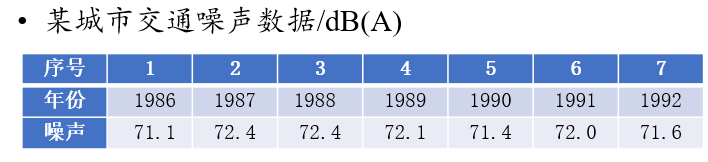

## 原始数据级比检验

计算$\lambda(k)=\frac{x^{(0)}(k-1)}{x^{(0)}(k)}$，`如果所有`$\lambda(k)$在区间$\left(e^{-\frac{2}{n+1}}, e^{\frac{2}{n+2}}\right)$`内，说明可用`GM(1,1)`模型`

clc,clear
x0=[71.1 72.4 72.4 72.1 71.4 72.0 71.6]'; % 注意这里为列向量
n=length(x0);
lamda=x0(1:n-1)./x0(2:n);  % 计算级比
range=minmax(lamda');      % 计算级比的范围
lamrange_min=exp(-2/(n+1));     % 允许的范围下界
lamrange_max=exp(2/(n+1));      % 允许的范围上界
% 原始数据的级比检验
if (range(1)>lamrange_min && range(2)<lamrange_max)
    fprintf("原始数据通过级比检验")
else
    fprintf("原始数据未能通过级比检验！！！")
    return
end

## 最小二乘法求微分方程参数

离散形式下，且均值处理后的方程：$x^{(0)}(t)=u-a z^{(1)}(t)$

其中$z^{(1)}(t)=0.5 x^{(1)}(t)+0.5 x^{(1)}(t-1)$

以方程矩阵形式Y=BU求出U

x1=cumsum(x0)  %累加序列
B=[-0.5*(x1(1:n-1)+x1(2:n)),ones(n-1,1)];
Y=x0(2:n);
% 注意此处是反斜杠，即左除
u=B\Y       % 拟合参数u(1)=a,u(2)=b

## 求解微分方程

以符号解的形式求出，就是求出表达式

注意：代码中的x是模型中的累加序列，x0是模型中的原始序列

此处**代码中累加序列函数表达式的自变量取值与模型中的下标不一致**

代码中的累加序列x是以函数的形式表示的，x(0)实际意义是累加序列第1年的数值！！！所以对应地，x(1)代表第2年，一直到x(n-1)年代表第n

**即代码中的x(k)，对应模型中的**${\;x}^{\left(1\right)} \left(k+1\right)$

syms x(t)   %定义符号变量

%dsolve求微分方程的符号解，即累加序列的函数表达式，而不是数值
x=dsolve(diff(x)+u(1)*x==u(2),x(0)==x0(1));     % diff是一阶导或差分
xt=vpa(x,6) %以保留6位小数的格式显示微分方程的解,vpa设置精度

% 函数subs(x,t,[0:n-1])意味着把t=0到t=n-1依次代入x的表达式求出值
nihe1=subs(x,t,[0:n-1]); %求已知数据对应的拟合值
nihe1=double(nihe1);     %符号数转换成数值类型，否则无法作差分运算
nihe=[x0(1),diff(nihe1)] %差分运算，得到原始序列拟合值

预测下一年的道路噪声平均声级，模型中：$\hat{x}^{(0)}(8)=\hat{x}^{(1)}(8)-\hat{x}^{(1)}(7)$

对应代码中：t=7时的x，减去t=6时的x

因为x是函数表达式，需要用subs代入自变量取值，再用double转为数值

yuce_result=double(subs(x,t,7))-double(subs(x,t,6))  % 原始序列的预测值，即第8年噪声

## 结果检验

相对误差检验和级比偏差检验

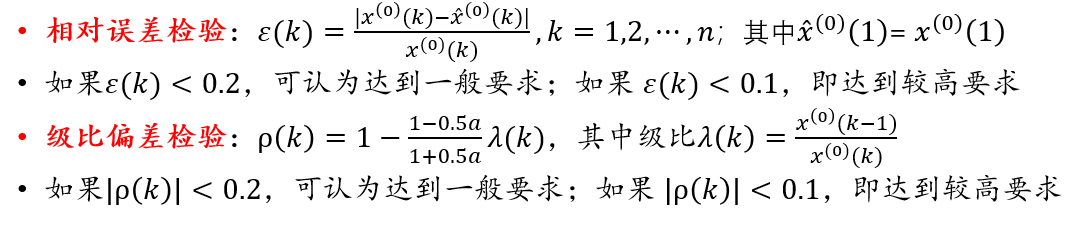

delta=abs((x0'-nihe )./x0')  %计算相对误差
rho=1-(1-0.5*u(1))/(1+0.5*u(1))*lamda'  %计算级比偏差值


% 本文件出自b站/公众号：数学建模BOOM
% 关注微信公众号：数学建模BOOM，回复"课程"
% 查看全套视频课程+配套PPT课件+代码文件
